clear all;
close all;
clc;    

impulse = zeros(1, 100);
impulse(50) = 1; % Assume the range of x is -49 to 50.  
impulse_fft = fft(impulse)

impulse_fft =    1.0000 + 0.0000i  -0.9980 - 0.0628i   0.9921 + 0.1253i  -0.9823 - 0.1874i   0.9686 + 0.2487i  -0.9511 - 0.3090i   0.9298 + 0.3681i  -0.9048 - 0.4258i   0.8763 + 0.4818i  -0.8443 - 0.5358i   0.8090 + 0.5878i  -0.7705 - 0.6374i   0.7290 + 0.6845i  -0.6845 - 0.7290i   0.6374 + 0.7705i  -0.5878 - 0.8090i   0.5358 + 0.8443i  -0.4818 - 0.8763i   0.4258 + 0.9048i  -0.3681 - 0.9298i   0.3090 + 0.9511i  -0.2487 - 0.9686i   0.1874 + 0.9823i  -0.1253 - 0.9921i   0.0628 + 0.9980i   0.0000 - 1.0000i  -0.0628 + 0.9980i   0.1253 - 0.9921i  -0.1874 + 0.9823i   0.2487 - 0.9686i  -0.3090 + 0.9511i   0.3681 - 0.9298i  -0.4258 + 0.9048i   0.4818 - 0.8763i  -0.5358 + 0.8443i   0.5878 - 0.8090i  -0.6374 + 0.7705i   0.6845 - 0.7290i  -0.7290 + 0.6845i   0.7705 - 0.6374i  -0.8090 + 0.5878i   0.8443 - 0.5358i  -0.8763 + 0.4818i   0.9048 - 0.4258i  -0.9298 + 0.3681i   0.9511 - 0.3090i  -0.9686 + 0.2487i   0.9823 - 0.1874i  -0.9921 + 0.1253i   0.9980 - 0.0628i


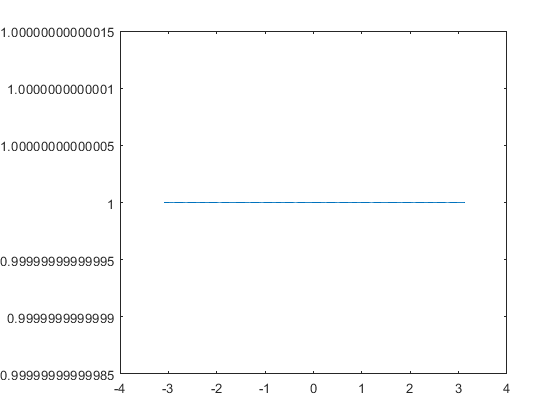

impulse_fft_mag = abs(impulse_fft);
omega = -49/50*pi : 1/50*pi : pi;
plot(omega, impulse_fft_mag)

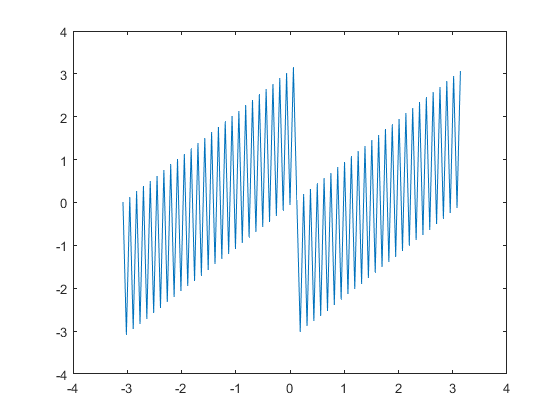

impulse_fft_angle = angle(impulse_fft);
figure
% unwraped_angle = unwrap(impluse_fft_angle);
plot(omega, impulse_fft_angle)

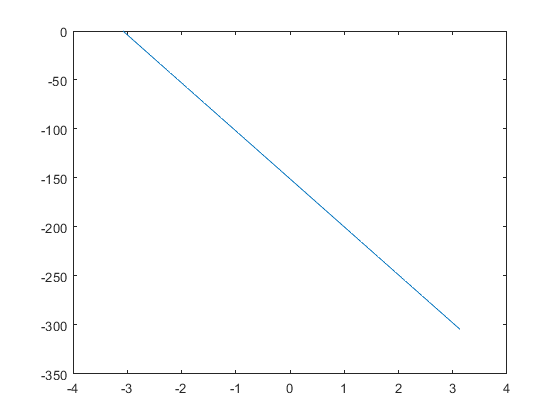

figure
unwraped_angle = unwrap(impulse_fft_angle);
plot(omega, unwraped_angle)

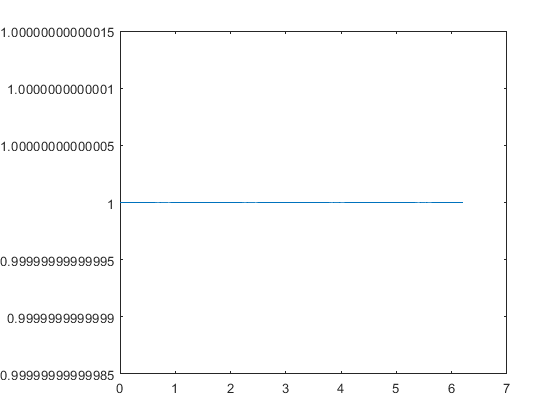

clear all;
close all;
clc;

impulse = zeros(1, 100);
impulse(80) = 1; % Set the value at delayed point to 1. which results in a delayed impulse function.  
impulse_fft = fft(impulse);
impulse_fft_mag = abs(impulse_fft);
% omega = -49/50*pi : 1/50*pi : pi;
omega = 0:pi/50:99/50*pi; 
plot(omega, impulse_fft_mag)

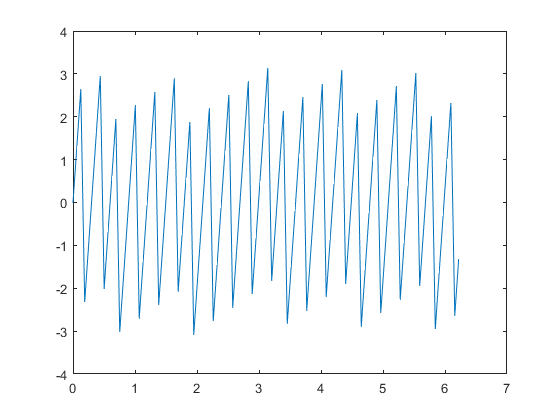

impulse_fft_angle = angle(impulse_fft);
figure
plot(omega, impulse_fft_angle)

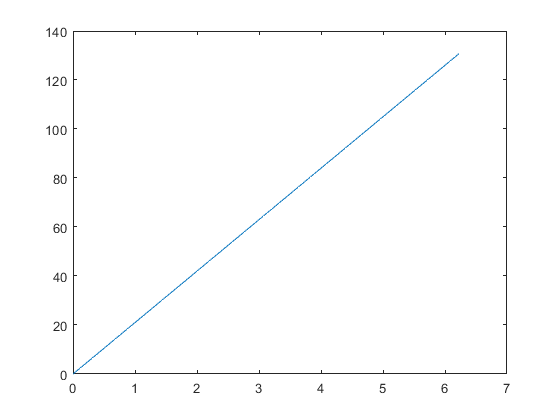

figure
unwraped_angle = unwrap(impulse_fft_angle);
plot(omega, unwraped_angle)